**SARAH AKTARI (part 1 - voltage trace, currents, f-I curve)**

**PARAMETER FOR CONOR-STEVENS MODEL (used from textbook)**

leak membrane potential was adjusted to better model a typical neuron at rest. the value of -17mV given by the textbook resulted in the model constantly firing action potentials as it was too positive and greater than the threshold value for action potentials. 

% parameters
C_m = 100; %pF membrane capcitance 

E_leak = -70; %mV leak reversal potential adjusted 
E_Na = 55; %mV sodium reversal potential
E_A = -75; %mV A-type potassium channel reversal potential 
E_K = -85; %mV potassium reversal potential 

G_leak = 30; %nS, leak conductance
g_Na_max = 12e3; %nS, maximum Na+ conductance
g_K_max = 2e3; %nS, maximun K+ conductance 
g_A_max = 4.77e3; %nS, maximum A-type conductance 

**Initialization of time, voltage, and gating variable vectors**

% time vector
dt = 0.01; %ms
tmax = 2000; %ms
time = (0:dt:tmax); %ms

% initialize vectors for variables
Vm = zeros(size(time)); %voltage vector
m = zeros(size(time)); % m gate vector variable in Na+ channel
n = zeros(size(time)); % h gate vector variable in Na+ channel
h = zeros(size(time)); % n gate vector variable in K+ channel
a = zeros(size(time)); % n gate vector variable in A-type potassium channel
b = zeros(size(time));% n gate vector variable in A-type potassium channel

Vm(1) = E_leak; %initialize voltage so at first index resting voltage is equal to leak conductance 

**Applied current vector and range **

% applied current vector 
I_app = zeros(size(time)); 

I_step = (0:100:3000); %vector of applied current intervals 

count_AP = zeros(size(I_step)); % vector to store number of action potentials fired for each applied current interval 

for i = 1 : length(I_step) % outer for loop going through each interval of applied current 
    I_app(:) = I_step(i);

% Currents for each channel with differential equations 
  I_leak = zeros(size(time)); %current vector for leak channels 
  I_Na = zeros(size(time)); %current vector for Na+ channels
  I_K = zeros(size(time)); %current vector for K+ channels 
  I_A = zeros(size(time)); %current vector for A-type channels

for t = 1:length(time)-1 % inner for loop to find values of voltage over time 

    %rate constants 

    % m gate variable : equations from textbook
    alpha_m = (0.38.*(Vm(t)+29.7))./(1-exp(-0.1.*(Vm(t)+29.7)));
    beta_m = 15.2.*exp(-0.0556.*(Vm(t)+54.7));

    tau_m = 1./(alpha_m+beta_m); %time constant for reference (used in last section)
    m_inf = alpha_m./(alpha_m+beta_m); %steady state equation for reference (used in last section)

    % h variable 
    alpha_h = 0.266.*exp(-0.05.*(Vm(t)+48));
    beta_h = 3.8./(1+exp(-0.1.*(Vm(t)+18)));

    tau_h = 1./(alpha_h+beta_h); %time constant 
    h_inf = alpha_h./(alpha_h+beta_h); %steady state equation 

    % n variable 
    alpha_n = (0.02.*(Vm(t)+45.7))./(1-exp(-0.1.*(Vm(t)+45.7)));
    beta_n = 0.25.*exp(-0.0125.*(Vm(t)+55.7));

    tau_n = 1./(alpha_n+beta_n); %time constant for reference (used in last section)
    n_inf = alpha_n./(alpha_n+beta_n); %steady state equation 

    % a variable 
    a_inf = ((0.0761.*exp(0.0314.*(Vm(t))))./(1+exp(0.0346.*(Vm(t)+1.17))))^(1/3); %steady state equation 
    tau_a = 0.3632 + (1.158./(1+exp(0.0497.*(Vm(t)+55.96)))); %time constant for reference (used in last section)

    % b variable 
    b_inf = (1./(1+exp(0.0497.*(Vm(t)+53.3))))^4; %steady state equation
    tau_b = 1.24 + (2.678./(1+exp(0.0624.*(Vm(t)+50)))); %time constant for reference (used in last section)

 % initial condition for the gating variables for first index
 %  set first index of each gating variable to steady state value
    if t==1
        m(1) = m_inf;
        n(1) = n_inf;
        h(1) = h_inf;
        a(1) = a_inf;
        b(1) = b_inf;
    end

    % caluclate differential equations for each variable  
    
    % dm/dt
    dm = (alpha_m*(1-m(t)) - beta_m*(m(t)))*dt;
    m(t+1) = m(t) + dm;

    % dn/dt
    dn = (alpha_n*(1-n(t)) - beta_n*(n(t)))*dt;
    n(t+1) = n(t) + dn;

    % dh/dt
    dh = (alpha_h*(1-h(t)) - beta_h*(h(t)))*dt;
    h(t+1) = h(t) + dh;

    % da/dt
    da = ((a_inf-a(t))/tau_a)*dt; 
    a(t+1) = a(t) + da;

    % db/dt
    db = ((b_inf-b(t))/tau_b)*dt; 
    b(t+1) = b(t) + db;

    % each chunk of differential equation 
    I_leak(t) = -G_leak*(E_leak-Vm(t)); %l eak current
    I_Na(t) = -g_Na_max*m(t)*m(t)*m(t)*h(t)*(E_Na - Vm(t)); % Na current
    I_K(t) = -g_K_max*n(t)*n(t)*n(t)*n(t)*(E_K - Vm(t)); % K current
    I_A(t) = -g_A_max*a(t)*a(t)*a(t)*b(t)*(E_A - Vm(t)); % A-type current

    % the complete differential eqn for the membrane voltage
    dV = ((-I_leak(t) - I_Na(t) - I_K(t) - I_A(t) + I_app(t))/C_m)*dt; % negate to account for sign 
    Vm(t+1) = Vm(t) + dV;
end

    count_AP(i) = numel(findpeaks(Vm)); %counts peaks of action potentials after each applied current 

end 

rate_AP = count_AP ./ (tmax * 1e-3); %records firing rate in spikes per second


**Plot of each gating variable against time **

Plots are all zoomed in on the 50 ms time interval because this model fires a lot of action potentials in short periods of time. the smaller time frame allows us to visualize how the gating variables, currents, and voltages change. 

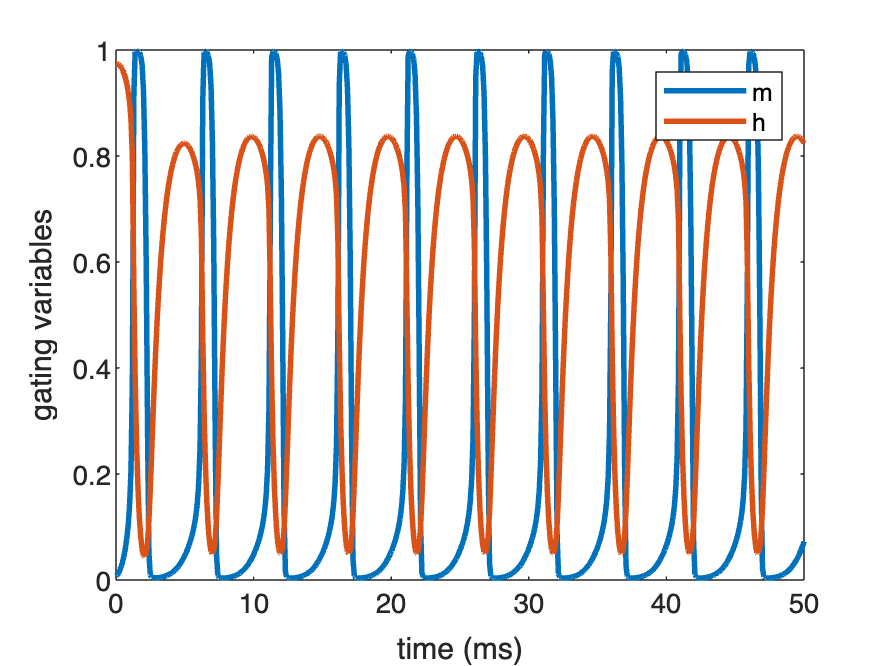

% figure of gating variables here

% Na+ channel gating variables 
figure % plot m and h gating variables over 50 ms
plot (time, m, 'LineWidth',2)
hold on
plot (time, h, 'LineWidth',2)
legend ('m', 'h')
xlabel ('time (ms)')
ylabel ('gating variables')
xlim([0 50])

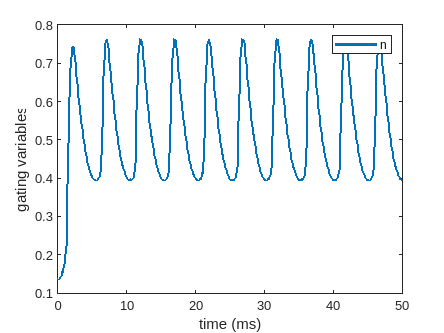


% voltage gated K+ channel gating variables
figure % plot n gating variable over 50 ms
plot (time, n, 'LineWidth',2)
legend ('n')
xlabel ('time (ms)')
ylabel ('gating variables')
xlim([0 50])

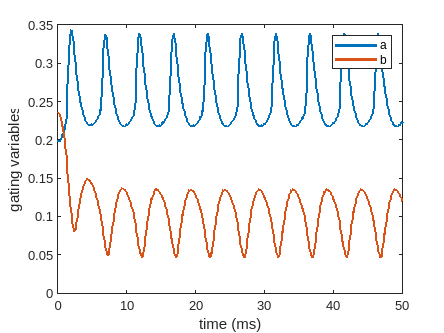


% A -type channel gating variables 
figure % plot a and b gating variables over 50 ms
plot (time, a, 'LineWidth',2)
hold on 
plot (time, b, 'LineWidth',2)
legend ('a', 'b')
xlabel ('time (ms)')
ylabel ('gating variables')
xlim([0 50])

**Voltage against time with applied current**

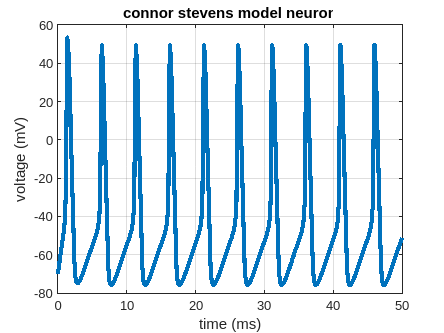

% plot of voltage against time for 3000pA applied current over 50 ms
figure;

plot(time,Vm,'LineWidth',3); grid on

xlabel('time (ms)')
ylabel('voltage (mV)')
title('connor stevens model neuron')

xlim([0 50])

**Current of each channel against time **

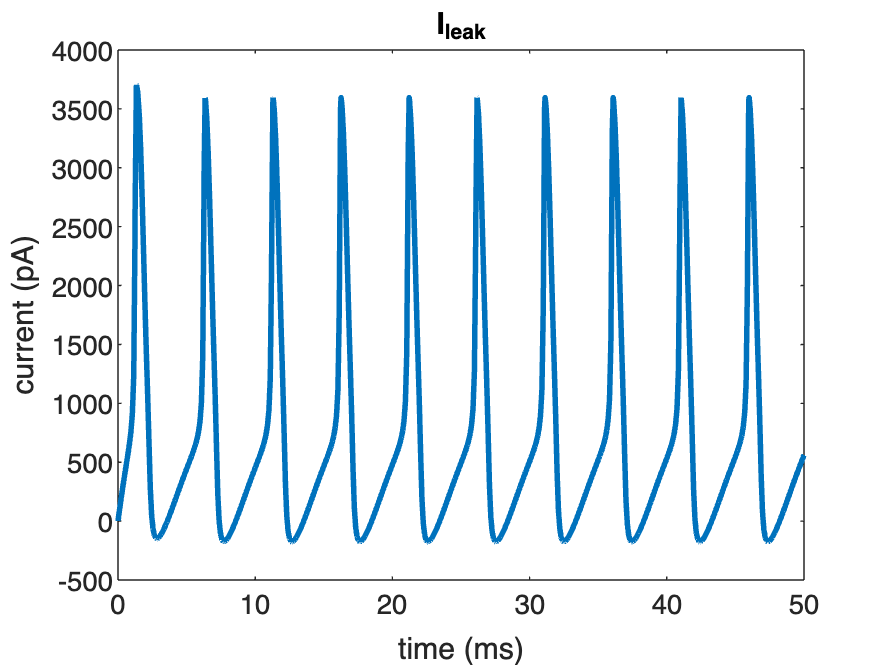

%plot of current against time 

figure % plot of leak current
plot (time, I_leak, 'LineWidth',2)
xlabel ('time (ms)')
ylabel ('current (pA)')
title ('I_{leak}')
xlim([0 50])

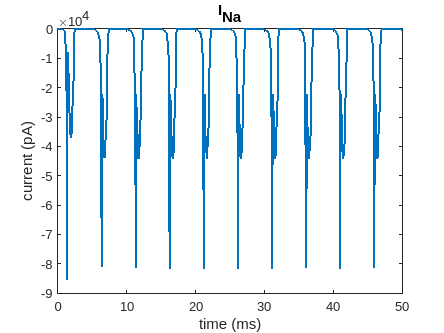


figure % plot of sodium current
plot (time, I_Na, 'LineWidth',2)
xlabel ('time (ms)')
ylabel ('current (pA)')
title ('I_{Na}')
xlim([0 50])

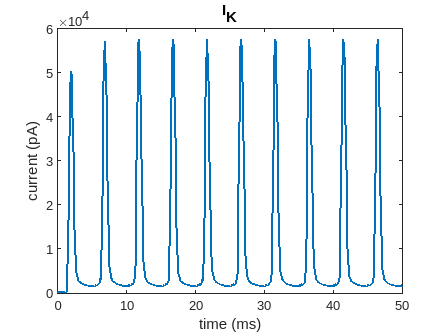


figure % plot of potassium current
plot (time, I_K, 'LineWidth',2)
xlabel ('time (ms)')
ylabel ('current (pA)')
title ('I_{K}')
xlim([0 50])

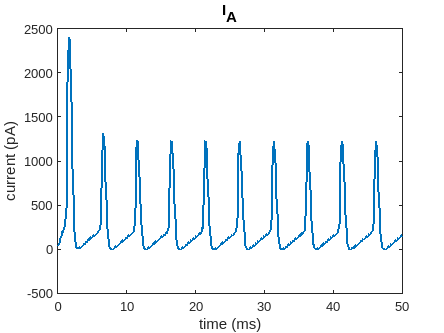


figure % plot of A-type current 
plot (time, I_A, 'LineWidth',2)
xlabel ('time (ms)')
ylabel ('current (pA)')
title ('I_{A}')
xlim([0 50])

**Plotting firing rate for each applied current **

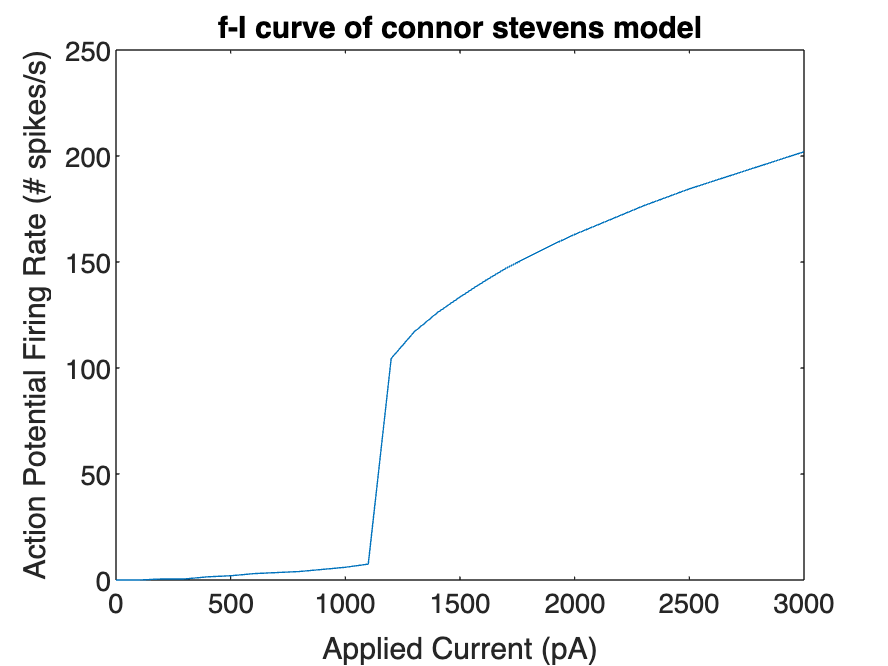

% equation used to count number of action potentials for each I_app
%count_AP = numel(findpeaks(Vm)

figure % plotting f-I curve: this is a type II neuron
plot (I_step, rate_AP)
xlabel ('Applied Current (pA)')
ylabel ('Action Potential Firing Rate (# spikes/s)')
title ('f-I curve of connor stevens model')